A script to show what the effects are of varying the initial amount of mannose

Report the mannose amount in mmol, %biomass weight, and relative to glc molecules from full conversion

Use a layout set up from args.p2


args.p2.v.anaerobic = true;
args.p2.v.maxcycles = 3500;
args.p2.v.timestep = 1;

args.p2.v.alpha = 0.03;
args.p2.v.km_cel = .7;
args.p2.v.kcat_cel = 32;
args.p2.v.addEnzymeToMaint = false;
args.p2.v.initcellulose = args.default.v.initcellulose * 0.27;


v = args.p2.v;



model = prepareYeastGEMModel('model',args.p2.model,'v',v);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

model.v = v;
layout = buildCelOptLayout(model);

layout.params.maxCycles = 4000;

factors = [0.5 0.75 1 2 4 10];
amts = args.p2.v.initman * factors;

t = table();
t.amt = amts';
t.yield = zeros(size(t.amt));
t.biomass = cell(size(t.amt));
t.media = cell(size(t.amt));
for i = 1:length(amts)
    layout = setMedia(layout,'man-D[e]',amts(i));
    runComets(layout);
    bio = parseBiomassLog(layout.params.biomassLogName);
    t.biomass{i} = bio;
    media = parseMediaLog(layout.params.mediaLogName,{'man-D[e]','glc-D[e]','cellulose','enzyme[e]'});
    t.media{i} = media;
end

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS exe


mannose_weight = 180.156; %g/mol
t.pct_biomass = (t.amt * mannose_weight / 1000) / args.p2.v.initialpop;
t.pct_glc = (t.amt * mannose_weight / 1000) / (args.p2.v.initcellulose * args.p2.v.glcpercellulose * (180.156 - 17) / 1000)

t = 6×6 table
       amt        yield       biomass             media         pct_biomass     pct_glc  
    __________    _____    ______________    _______________    ___________    __________

    0.00074935      0      {4001×7 table}    {16004×6 table}        1000       0.00030375
      0.001124      0      {4001×7 table}    {16004×6 table}        1500       0.00045563
     0.0014987      0      {4001×7 table}    {16004×6 table}        2000        0.0006075
     0.0029974      0      {4001×7 table}    {16004×6 table}        4000         0.001215
     0.0059948      0      {4001×7 table}    {16004×6 table}        8000          0.00243
      0.014987      0      {4001×7 table}    {16004×6 table}       20000         0.006075


t.pct_yield = zeros(size(t.amt));% init mannose as percent of yield
for i = 1:length(factors)
    t.pct_yield(i) = (t.amt(i) * mannose_weight / 1000) / max(t.biomass{i}.biomass);
end

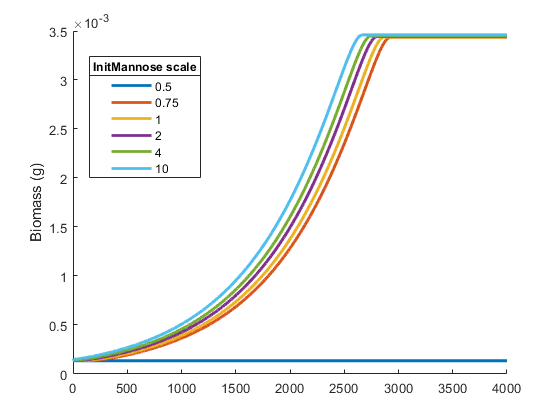

%Plot the biomass
figure;
hold on;
for i = 1:length(t.biomass)
    b = t.biomass{i};   
    plot(b.t,b.biomass,'LineWidth',2,'DisplayName',num2str(factors(i)))
end
ylabel('Biomass (g)');
leg = legend('location','best');
title(leg,'InitMannose scale');
hold off;

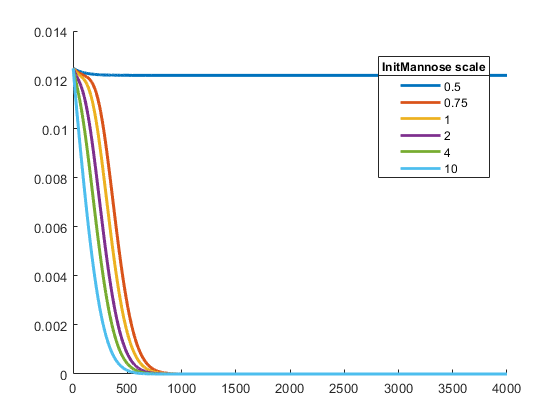


%check for total cellulose conversion
figure;
hold on;
for i = 1:length(t.media)
    m = t.media{i};
    a = m(stridx('cellulose',m.metname),:);
    
    plot(a.t,a.amt,'LineWidth',2,'DisplayName',num2str(factors(i)))
end
leg = legend('location','best');
title(leg,'InitMannose scale');
hold off;

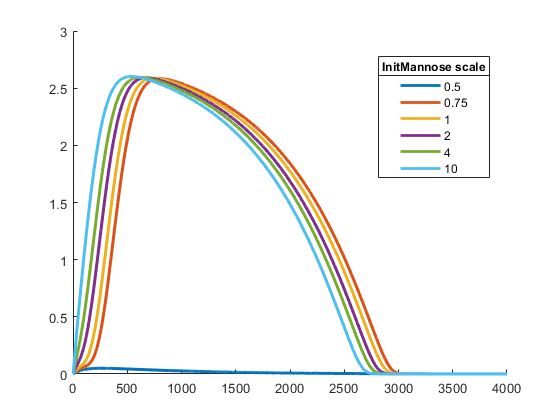


%check glc amount
figure;
hold on;
for i = 1:length(t.media)
    m = t.media{i};
    a = m(stridx('glc-D[e]',m.metname),:);
    
    plot(a.t,a.amt,'LineWidth',2,'DisplayName',num2str(factors(i)))
end
leg = legend('location','best');
title(leg,'InitMannose scale');
hold off;

% Time to termination
x = t.biomass{factors==1};
d1 = x.biomass(2:end) - x.biomass(1:end-1);
x = t.biomass{factors==10};
d2 = x.biomass(2:end) - x.biomass(1:end-1);
endat1 = sum(d1 > 0);
endat10 = sum(d2 > 0);
endat10/endat1

ans = 0.9461

endat1/endat10

ans = 1.0570